# Median Filter

- removes large spikes

- first sort, then select median 

## Generate a test signal

- use integrated white noise, for example

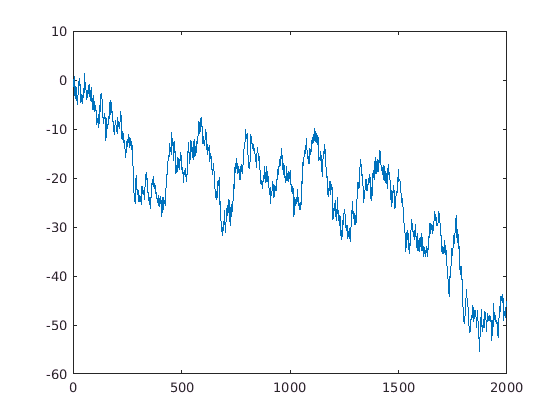

n = 2000;
signal = cumsum(randn(n,1));
plot(signal);

## Generate random spikes

Pspike = .03; %probability of spikes in signal
m = round(n*Pspike); %number of spikes in the signal
loc_spikes = randperm(n, m); %creates a vector of random integers from 1 to n

## Add spikes to the signal

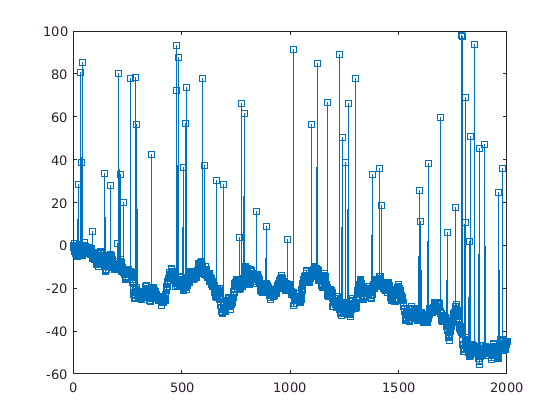

signal(loc_spikes) = rand(size(loc_spikes))*100;
figure(1);
plot(signal, 's-'); %use squares to show the spikes are single point spikes

## Find a threshold to filter

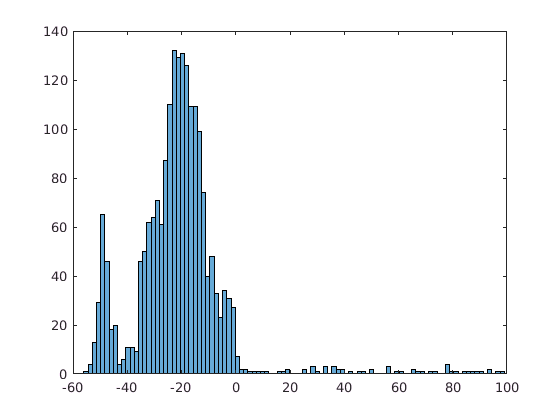

figure(2);
histogram(signal, 100);

thresh = 0;
noise = find(signal>thresh);

## Filter signal points larger than threshold

filtered = signal;
k = 20; %half of window, which is k*2 + 1

for i=1:length(noise)
    lower = max(1, noise(i)-k); %to prevent lower bounds < the first datapoint
    upper = min(noise(i)+k, n); %to prevent upper bounds > the last datapoint
    filtered(noise(i)) = median(signal(lower:upper));
end

## Plot the filtered signal

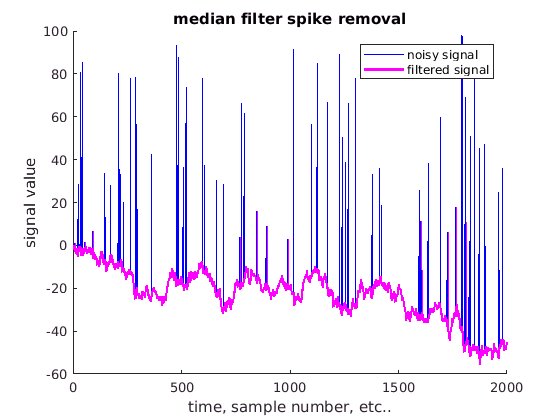

figure(3);
hold on;
sig_plot = plot(1:n, signal, 'b', 'linew', 1);
filt_plot = plot(1:n, filtered, 'm', 'linew', 2);
xlabel("time, sample number, etc..");
ylabel("signal value");
title("median filter spike removal");
legend([sig_plot, filt_plot], ["noisy signal", "filtered signal"]);
hold off;

## Filtering the entire signal

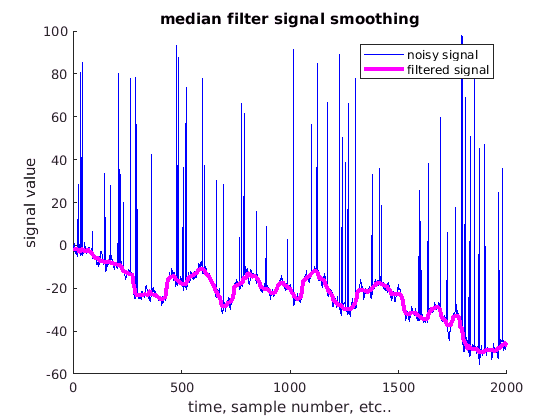

noise = 1:n;
filtered = signal;
k = 20; %half of window, which is k*2 + 1

for i=1:length(noise)
    lower = max(1, noise(i)-k); %to prevent lower bounds < the first datapoint
    upper = min(noise(i)+k, n); %to prevent upper bounds > the last datapoint
    filtered(noise(i)) = median(signal(lower:upper));
end

figure(4);
hold on;
sig_plot = plot(1:n, signal, 'b', 'linew', 1);
filt_plot = plot(1:n, filtered, 'm', 'linew', 3);
xlabel("time, sample number, etc..");
ylabel("signal value");
title("median filter signal smoothing");
legend([sig_plot, filt_plot], ["noisy signal", "filtered signal"]);
hold off;